# BE2 - Synthèse par représentation d’état - Commande LQ

% A, B, C sont les matrices de l'espace d'état 
A=[-0.02 1 1; -0.01 -1 0 ; 0 1 0];
B=[1.6 ; 0.23 ; 0];
C=[1 0 0];
D=0;

**1 Synthèse du correcteur par placement de pôles**

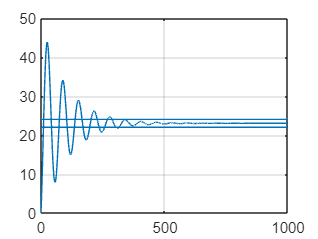

% Calcul des valeurs propres de la matrice A
VP = eig(A); % stable car VP négative réelle

% Conversion de la représentation d'état en fonction de transfert
[de, q] = ss2tf(A, B, C, 0);
numerators = [de];
denominator = [q];

% Création du modèle de système de transfert
sys = tf(numerators, denominator);

% Définition du temps de simulation
t = 0:0.1:1000;

% Calcul de la réponse indicielle (étape) du système
y = step(sys, t);

% Tracé de la réponse indicielle
plot(t, y)
grid on

% Ajout de lignes pour indiquer les valeurs de référence (24 et 22)
line([0 1000], [24 24])
line([0 1000], [22 22], 'color', 'g')
line([0 1000], [24 24])
line([0 1000], [22 22])

**Q4)**

% Définition d'un vecteur de zéros de taille 3x1
zerotroisun = [0; 0; 0]; % ou zerotroisun = zeros(3,1);

% Construction de la matrice étendue Ae
Ae = [A zerotroisun; C 0];

% Construction du vecteur étendu Be
Be = [B; 0];

% Définition des paramètres espsil, wn
espsil = sqrt(2)/2;
wn = 1;

% Calcul des valeurs propres désirées
lambda1 = -espsil * wn + 1i * wn * sqrt(1 - espsil^2);
lambda2 = -espsil * wn - 1i * wn * sqrt(1 - espsil^2);
lambda3 = lambda1 * 100;
lambda4 = lambda2 * 100;

% Placement des pôles pour obtenir la matrice de gain Ke
Ke = place(Ae, Be, [lambda1, lambda2, lambda3, lambda4]);

% Extraction des composantes nécessaires de la matrice de gain Ke
K = Ke(1:3);
Ki = Ke(4);


**2 Synthèse du correcteur via la commande LQ **

% Définition d'un vecteur v
v = [1 1 1 1000];

% Création d'une matrice diagonale Q à partir du vecteur v
Q = diag(v);

% Définition de la matrice R
R = 1;

% Calcul du gain LQR KeLQ
KeLQ = lqr(Ae, Be, Q, R);

% Extraction des composantes nécessaires de la matrice de gain KeLQ
KLQ = KeLQ(1:3);
KiLQ = KeLQ(4);


**3 Synthèse d’un observateur**

le systeme n'est pas observable car C CA CA^2 n est pas de rang 3

% Définition des valeurs propres désirées pour l'observateur
lambdaobs1 = -1;
lambdaobs2 = lambda3;
lambdaobs3 = lambda4;

% Placement des pôles pour obtenir la matrice de gain Gt
Gt = place(transpose(A), transpose(C), [lambdaobs1, lambdaobs2, lambdaobs3]);

% Transposition de la matrice de gain Gt pour obtenir la matrice G
G = transpose(Gt);


marges gain et phase /pôles 

% Création du système interne en boucle fermée
sysint = ss(A - B * KLQ, B, C, 0);

% Conversion du système interne en fonction de transfert
G1 = tf(sysint);

% Création de la fonction de transfert en boucle ouverte FTBO
s = tf('s');
FTBO = KiLQ * G1 / s;

% Affichage des pôles, zéros et gain de la fonction de transfert FTBO
zpk(FTBO)

ans =
 
    50.596 (s+1) (s+0.1438)
  ----------------------------
  s (s+10.19) (s+1) (s+0.1437)
 
Continuous-time zero/pole/gain model.
Model Properties


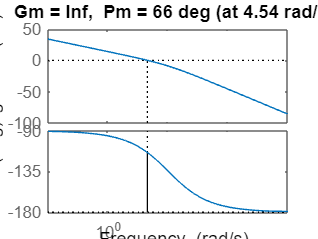


% Calcul et tracé des marges de gain et de phase
margin(FTBO)

% Désactivation de la superposition de graphiques sur le même axe
hold off

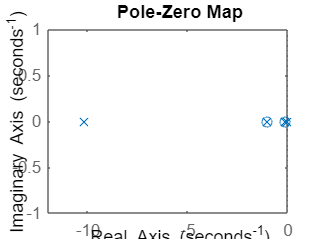


% Tracé du diagramme de pôles et zéros de la fonction de transfert FTBO
pzmap(FTBO)


% Affichage des pôles, zéros et gain du système d'origine
zpk(ss(A, B, C, 0))

ans =
 
     1.6 (s+1) (s+0.1437)
  --------------------------
  (s+1) (s^2 + 0.02s + 0.01)
 
Continuous-time zero/pole/gain model.
Model Properties
